# Graphics Arrays

Instructions are in the task pane to the left. Complete and submit each task one at a time.

This code sets up the activity.

avgEventsPerDecade = [  74.2 83.8 99.2 159;
                        29 34 31.2 45];
grps = ["All Events" "US Events"];
labs = ["1800s" "First half of 1900s" "Second half of 1900s" "2000s"];
numEvents = [89; 82; 84; 61; 71; 110; 93; 104; 95; 94; 93; 110; 152; 19];
avgEventsPerDecade

avgEventsPerDecade =    74.2000   83.8000   99.2000  159.0000
   29.0000   34.0000   31.2000   45.0000


## Task 1

In previous practices, you manipulated the properties of multiple graphics in one visualization. Recall that the `geoscatter` and `geoplot` functions created two separate plotting objects that you modified.

Some functions create an array of graphics objects. For instance, bar graphs of a matrix with *n* columns will create a **bar** array with *n* elements.

b = bar(avgEventsPerDecade)

b =   1×4 Bar array:

    Bar    Bar    Bar    Bar


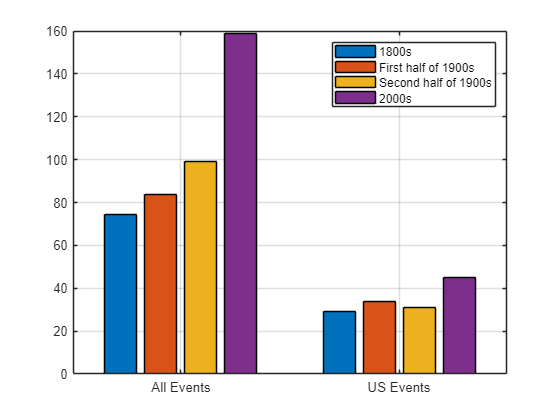

xticklabels(grps)
legend(labs)
grid on

## Task 2

To edit individual bars, you can extract one by indexing the same way you do with vectors.

`barArray``(``n``)`

bar2 = b(2)

bar2 =   Bar (First half of 1900s) with properties:

    BarLayout: 'grouped'
     BarWidth: 0.8000
    FaceColor: [0.8500 0.3250 0.0980]
    EdgeColor: [0 0 0]
    BaseValue: 0
        XData: [1 2]
        YData: [83.8000 34]

  Show all properties


## Task 3

To emphasize the rising number of storms, you will make the third and fourth bars a darker shade of red using the color of the second bar as a base.

fc = bar2.FaceColor;

## Task 4

Set properties of individual bars using dot notation.

`barArray``(``n``)``.``PropertyName` `=`` value`

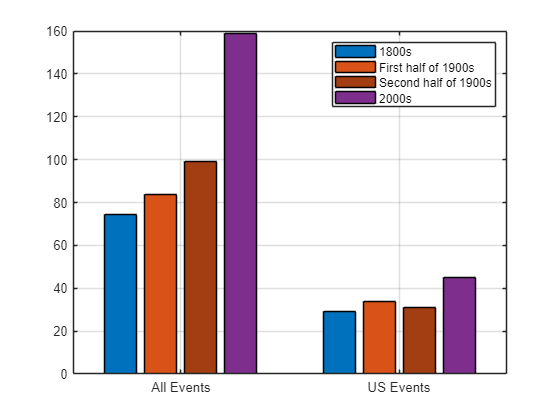

b(3).FaceColor = fc*.75;

## Task 5

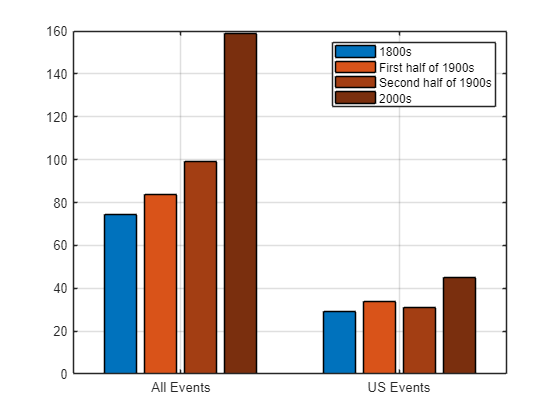

b(4).FaceColor = b(3).FaceColor*.75;

## Task 6

If you want to set the properties of all of the elements of a graphics array at the same time, you can use the `set` function.

`set``(``grArray``,``Property``,``newValue``)`

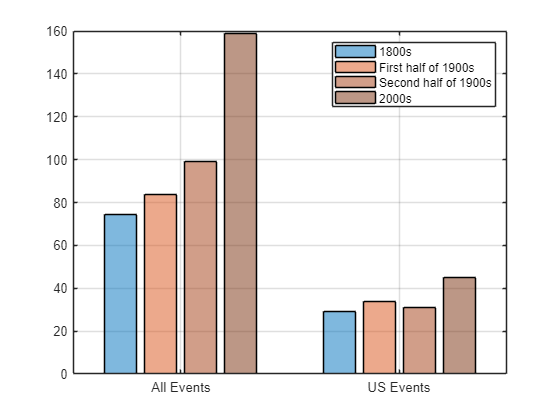

set(b,  "FaceAlpha", .5) 